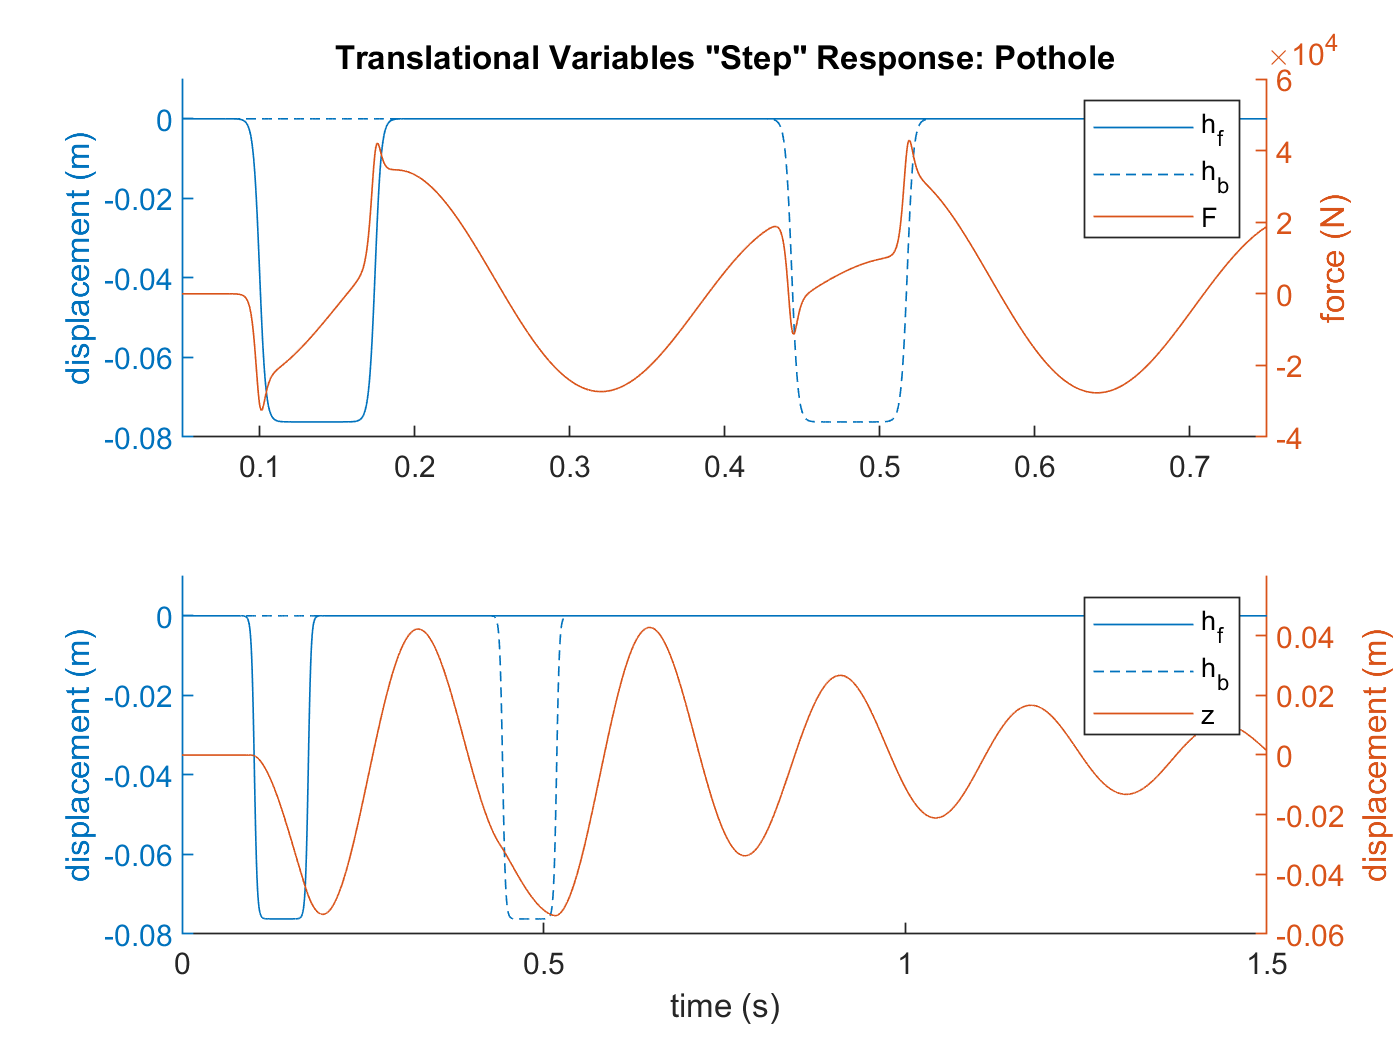

%simulation analysis
close all

t=out.tout;
h_f=out.h(:,1);
h_b=out.h(:,2);
z=out.x(:,1);
theta=out.x(:,2);
F=out.f(:,1);
N=out.f(:,2);

% plot(t,N)
% title('Torque')
% plot(t,F)
% title('Force')
% plot(t,z)
% title('Displacement')
% plot(t,theta)
% title('Angle')
% plot(t,h_f,t,h_b)
% title('Road Height')

figure
subplot(2,1,1);
hold on
yyaxis left
ylabel('displacement (m)')
plot(t(501:7500),h_f(501:7500))
plot(t(501:7500),h_b(501:7500))
ylim([-0.08,0.01])
yyaxis right
ylabel('force (N)')
plot(t(501:7500),F(501:7500))
xlim([t(501) t(7500)])
hold off
title('Translational Variables "Step" Response: Pothole')
legend('h_f','h_b','F','Location','northeast')

subplot(2,1,2);
hold on
yyaxis left
ylabel('displacement (m)')
plot(t,h_f)
plot(t,h_b)
ylim([-0.08,0.01])
yyaxis right
ylabel('displacement (m)')
plot(t,z)
hold off
xlabel('time (s)')
legend('h_f','h_b','z','Location','northeast')

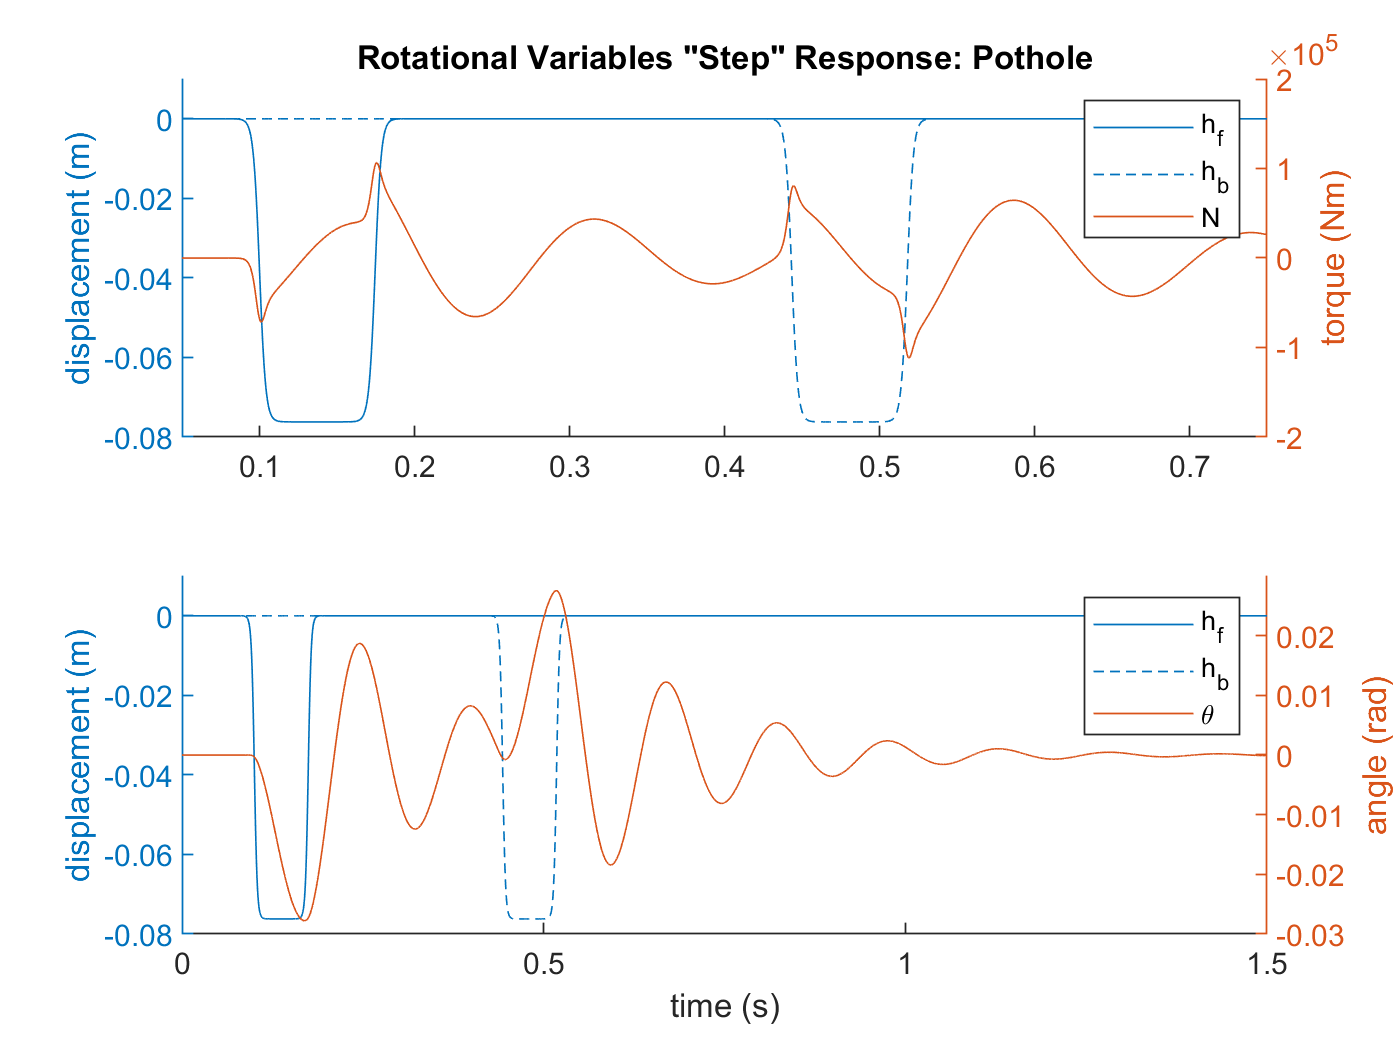


figure
subplot(2,1,1);
hold on
yyaxis left
ylabel('displacement (m)')
plot(t(501:7500),h_f(501:7500))
plot(t(501:7500),h_b(501:7500))
ylim([-0.08,0.01])
yyaxis right
ylabel('torque (Nm)')
plot(t(501:7500),N(501:7500))
xlim([t(501) t(7500)])
hold off
title('Rotational Variables "Step" Response: Pothole')
legend('h_f','h_b','N','Location','northeast')

subplot(2,1,2);
hold on
yyaxis left
ylabel('displacement (m)')
plot(t,h_f)
plot(t,h_b)
ylim([-0.08,0.01])
yyaxis right
ylabel('angle (rad)')
plot(t,theta)
hold off
xlabel('time (s)')
legend('h_f','h_b','\theta','Location','northeast')